clear; close; clc;
%Xav = Xal*psata / Xnl *psatn + Xal *psata

%define consts
psata = 8.142e4

psata = 81420

psatn = 3.907e4

psatn = 39070


figure;

samples = 1000

samples = 1000

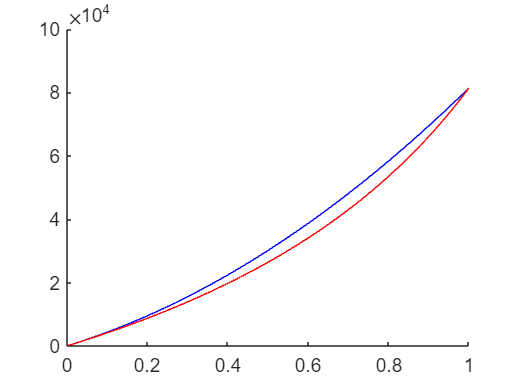

data = zeros(samples,5);

Xals = linspace(0.001,.999,samples);

for i = 1:samples
    % define molfrac liq
    Xal = vpa(Xals(i));
    Xnl = 1 - Xal;
    
    % definve molFrac vap from mol frac l
    Xav = Xal * psata / (Xnl *psatn + Xal *psata);
    Xnv = 1 - Xav;
    
    p = (Xal/Xav)*psata;
    
    pva = p*Xav;
    pvn = p*Xnv;
    
    pla = p*Xal;
    pln = p*Xnl;

    data(i,:) = [Xal,Xav,p,pla,pva];
end

figure; hold on;
plot(data(:,1),data(:,4),"-b");
plot(data(:,2),data(:,5),"-r")